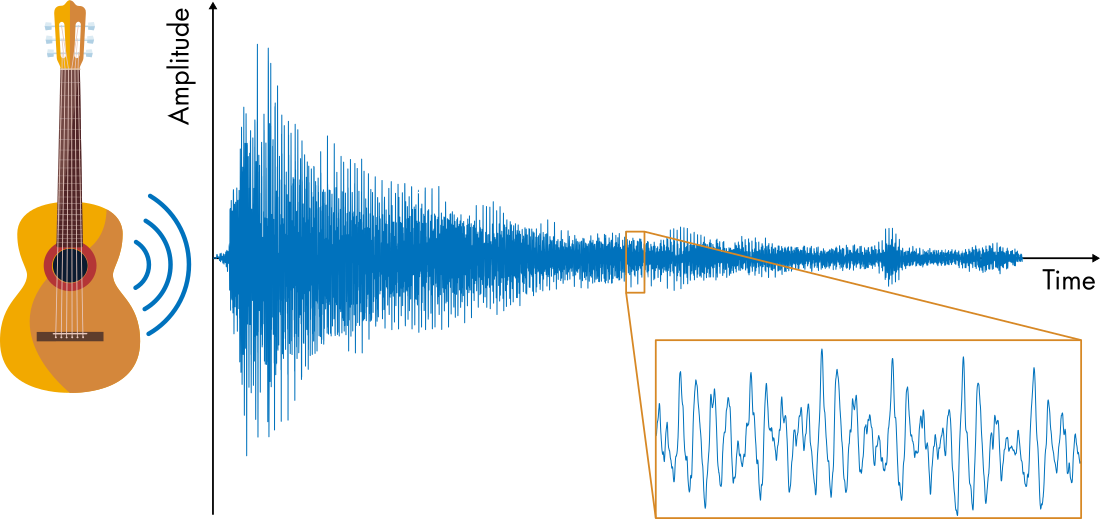

When a guitar is strummed, the vibration of the strings and guitar body emits a pressure wave. You can record that wave with a microphone, but analyzing it can daunting. There's just so much going on. However, zoom in on the audio signal, and you'll find a series of repeating patterns. Analyze the signal in the frequency domain, and you'll uncover what's really going on here.

# Fourier Series

**Learning Goals**

- Compare signals in the time and frequency domains.

- Analyze the frequencies present in audio signals.

- Visualize Fourier series modes.

- Describe how phase shift is represented in a Fourier series

- Compute the Fourier series of a periodic function.

## The Frequency Domain

Fourier analysis is all about taking signals from the time domain (or spatial domain) and analyzing them in the *frequency domain*. 

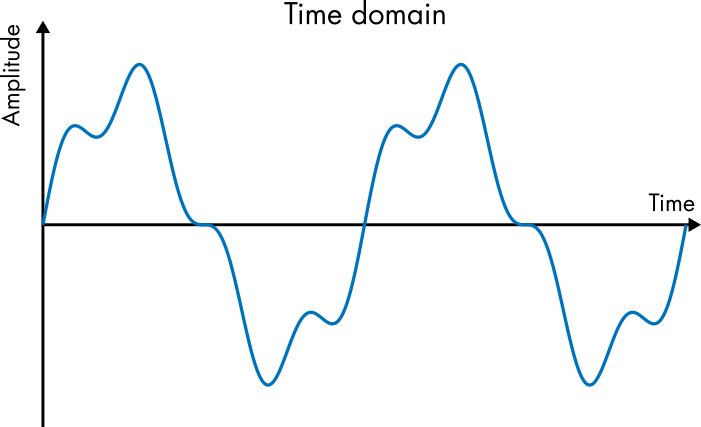      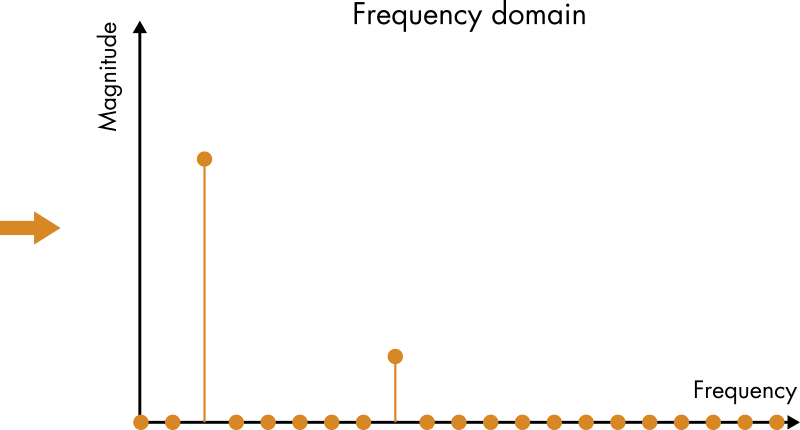

*A signal in the time and frequency domains. While the signal has a a lot going on in the time domain, it actually a simple sum of two sine functions, as illustrated in the frequency domain.*

Each frequency present in a signal creates a peak in the frequency domain. The stronger that frequency is in the signal, the larger the peak is in the frequency domain. 

### A Single Sine Function

Consider the function 


$$y(t) = A \sin( 2\pi f t)$$


This sine function has a frequency of $f$ Hz. Suppose that $f = 220$ Hz. When represented in the time domain, the function is plotted against time producing the usual sine curve. In the frequency domain, the function is represented by a single peak at 220 Hz. The amplitude $A$ determines the height of the peak in the frequency domain.

The plot illustrates $y$ in both the time and frequency domains. 

- What happens in each plot when you increase $f$, the frequency of the sine curve?

- How do the plots change when the amplitude $A$ is increased?

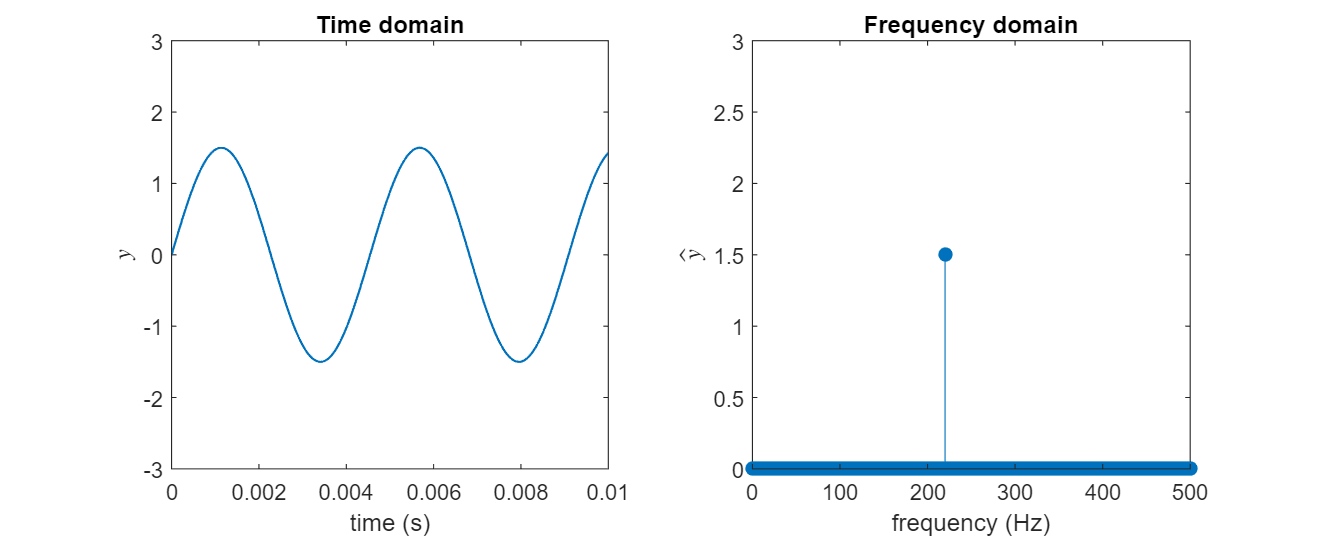

f = 220;
A = 1.5;
plotSingleSine(A, f); % Helper function that generates the plots

    **Activity. **A 220 Hz signal is special; it represents a "perfect" A note. You can listen to the 220 Hz signal by (1) generating the sine curve and (2) playing it as an audio signal.

**Task 1. **The time variable `t` has been created for you. Using `t`, create a signal, `y`, that is a sine wave with a frequency of 220 Hz with an amplitude $A = 1$. 

Fs = 44.1e3; % Audio sample rate
t = 0:1/Fs:1; % 1 second time variable
% Create your signal y here
y = sin(2*pi*220*t);

**Task 2.** Call the [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) function to play the audio signal using the syntax

where `y` is the signal and `Fs` is the sample rate. Then, run the section to play `y` as an audio signal.

% This code will play the audio signal
soundsc(y,Fs)

**Task 3. **If you divide or multiply the frequency by 2, you land on the same note, but an octave higher or lower. Try adjusting the frequency to 110 Hz to listen to A note one octave lower.

### **A Real Signal**

The pure 220 Hz note probably did not sound very appealing. Real sounds tend to have several complementary frequencies (known as harmonics) that create a richer sound. Listen to the guitar note played below.

[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)

You can analyze the guitar note in the time domain by plotting the audio signal. Below, about 10 miliseconds of the signal is plotted. 

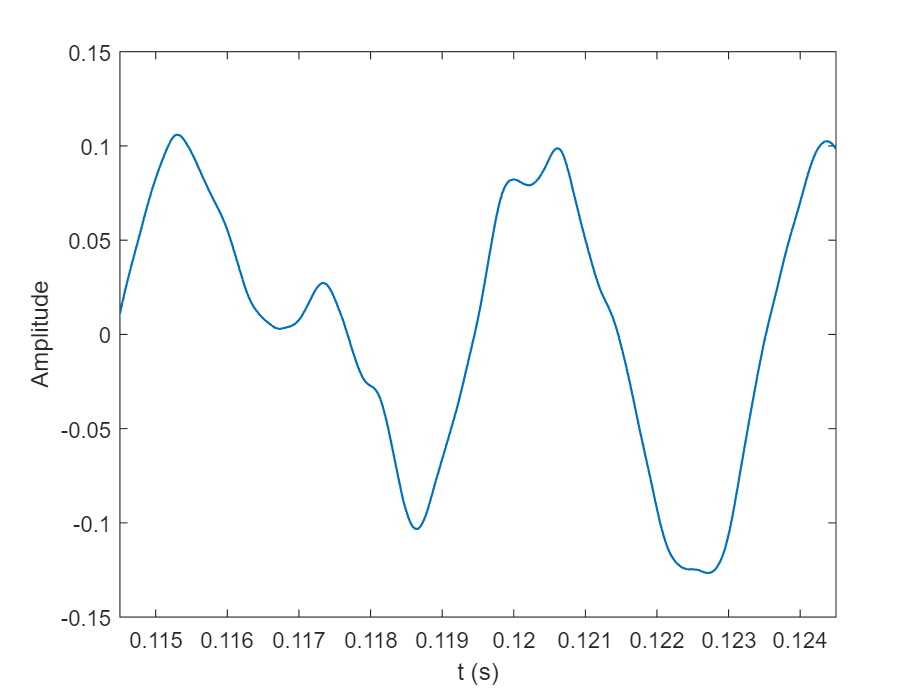

tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable
% Generate the plot
figure 
plot(tGuitar,yGuitar(:,1),"Linewidth",1)
xlim([0.1145,0.1245])
xlabel("t (s)")
ylabel("Amplitude")

**  Reflect.** 

- Compare this signal to the pure sine signal plotted in the previous activity. Can you pick out the dominant frequency(ies) in the guitar audio signal?

- In the frequency domain, how many peaks would you expect to see for the guitar signal?

 **Exercise. **Clearly, there's more to the guitar A note than the single root frequency. Consider the function


$$y(t) = b_1 \sin( 2\pi f_1 t) + b_2 \sin( 2\pi f_2 t) + b_3 \sin( 2\pi f_3 t) $$


where $b_i$ is the amplitude of component and $f_i$ is its frequency in Hz. Follow the steps below to design $y$ so that it sounds like the recording (well, as much as possible). The root frequency of the guitar's A note is 110 Hz, the first harmonic is 220 Hz, and the second harmonic is 330 Hz. Use these values for the frequencies of the signals. You can use the variable `t` to help you create your signal.

**Task 1. **Define the signal, `y`, in MATLAB.

Fs = 44.1e3; % Audio sample rate
t = 0:1/Fs:1; % 1 second time variable
% Define the coefficients b1, b2, and b3
b1 = 0.5;
b2 = 2;
b3 = 0.3;
% Define the frequencies f1, f2, and f3 in Hz
f1 = 110;
f2 = 220;
f3 = 330;
% Create the signal y
y = b1*sin(2*pi*f1*t) + b2*sin(2*pi*f2*t) + b3*sin(2*pi*f3*t);

**Task 2. **Plot the signal `y` against `t` using the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) function. Adjust the x-axis limits to `[0,0.01]` using the [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) function.

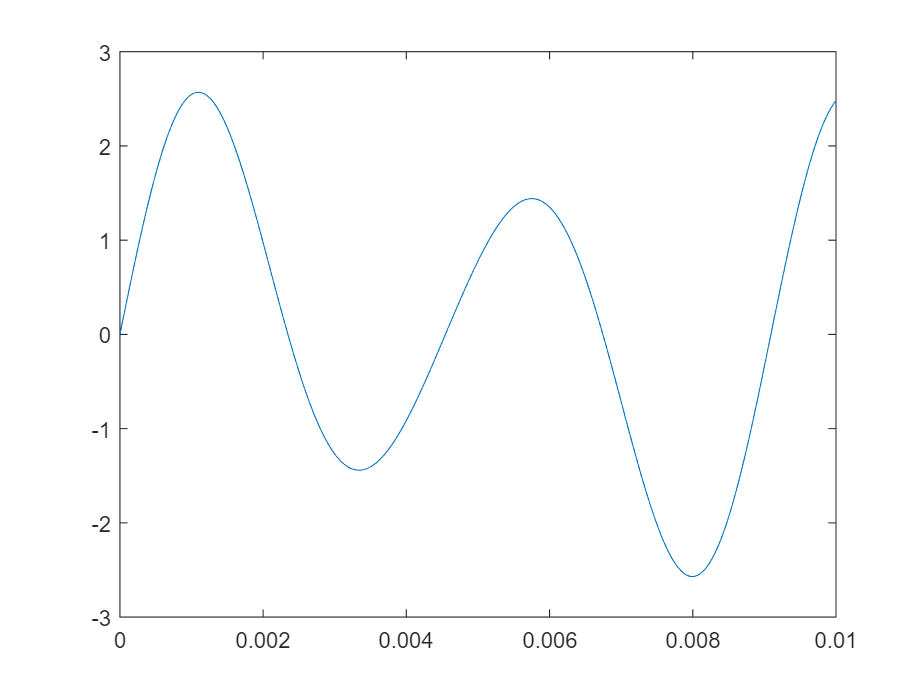

plot(t,y)
xlim([0,0.01])

**Task 3.** Use the [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) function to play your signal. 

soundsc(y,Fs)

**Task 4. **Adjust the coefficients `bi` so that the signal better replicates the guitar signal in both the plot and the sound. Note that it will never match perfectly, so only make 3 or 4 adjustments.

**  Reflect.** 

- Which frequency has the greatest amplitude (110 Hz, 220 Hz, or 330 Hz)?

- What is missing from $y(t)$ that is needed to reproduce the guitar signal?

## Fourier Sine and Cosine Series

To accurately reproduce a periodic real-world signal, it is often the case that more than 3 frequencies are required. Fourier series reproduce **periodic** signals using an infinite number of frequencies (in theory). In practical signal processing, only a finite number of frequencies are used. The *Fourier sine series *is an infinite sum of sine functions:


$$f(t) = \sum_{n=1}^\infty b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


Each term in the sum is known as a *Fourier* *mode*. $L$ is a parameter the determines the periodicity of the function $f$, which has period $2L$. The coefficients $b_n$ determine how strongly each mode is represented in the overall sum. 

    **Activity. **In this activity you will build several functions using the Sine and Cosine Series app. Click the link to open the app, then complete the tasks listed below.

[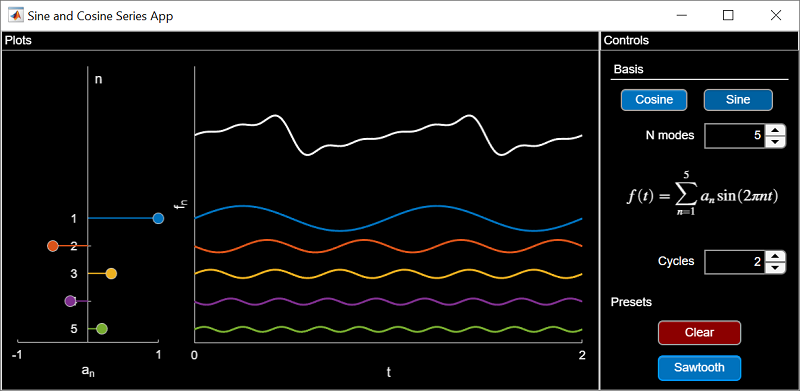](matlab: SinCosSeries)

[SinCosSeries.mlapp](matlab: SinCosSeries)

**Task 1. **Set the Fourier basis to Sine.

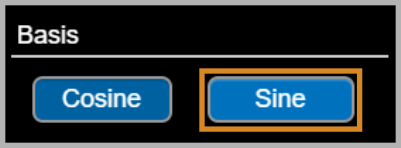

**Task 2. **Create the signal shown below by adjusting the values of the Fourier coefficients. To do so, click and drag the Fourier coefficients. These are located on the stem plot on the left.

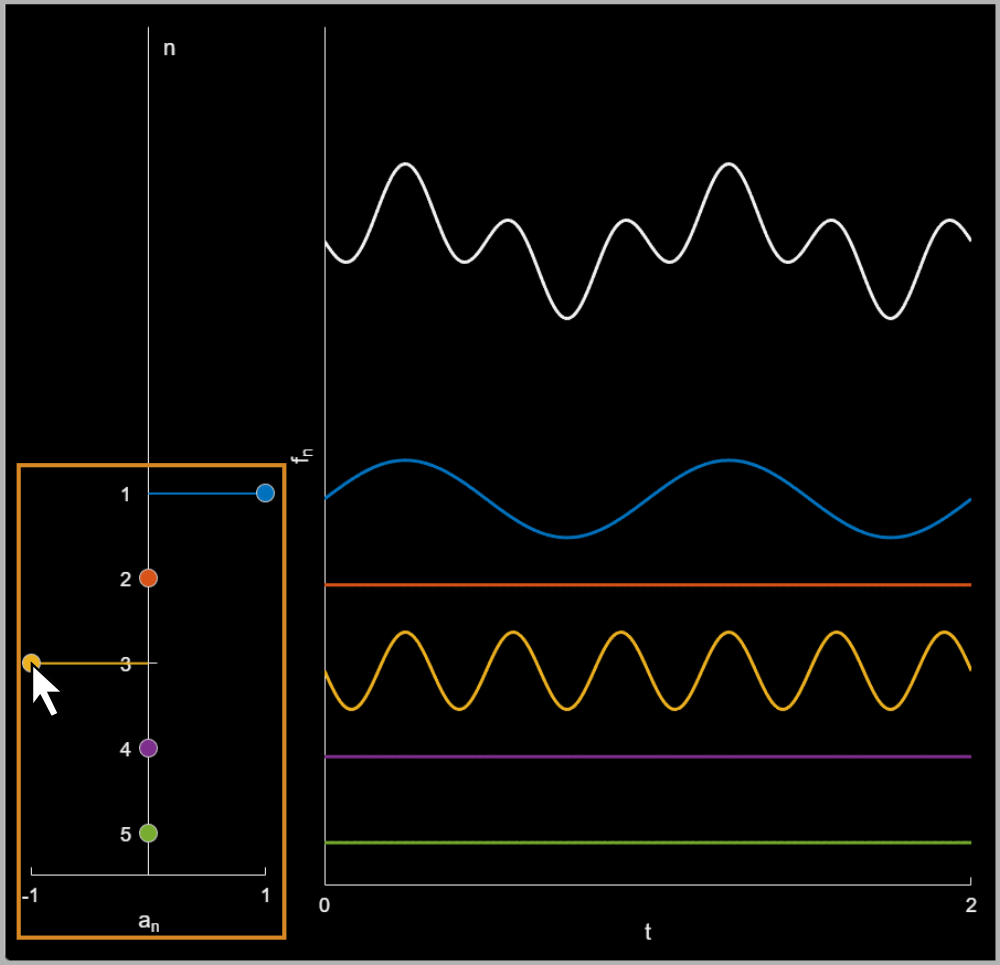

**Task 3. **Click the animate button to illustrate how the components are added to build the overall function.

**Task 4. **Adjust the Fourier coefficients to (approximately) $a_1 = 1$, $a_2 = 0.5$, $a_3 = 0.25$, $a_4 = 0.125$, $a_5 = 0.0625$ and animate the plot. What waveform is produced?

**Task 5. **Recreate the waveforms pictured below by adjusting the Fourier coefficients.

(a) 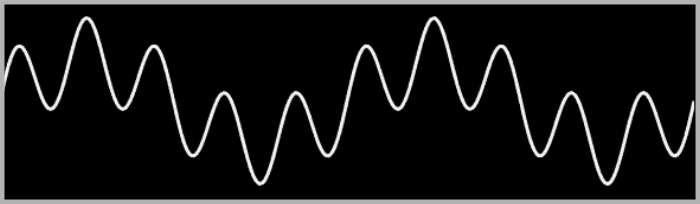

(b) 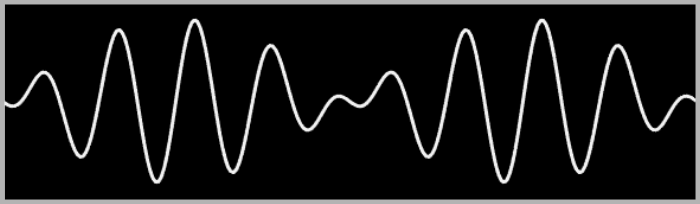

## Fourier Series

The Fourier sine series contains infinitely many frequencies. This allows the series to produce many different waveforms. However, all frequencies produced using only sine modes will have zero *phase*. 

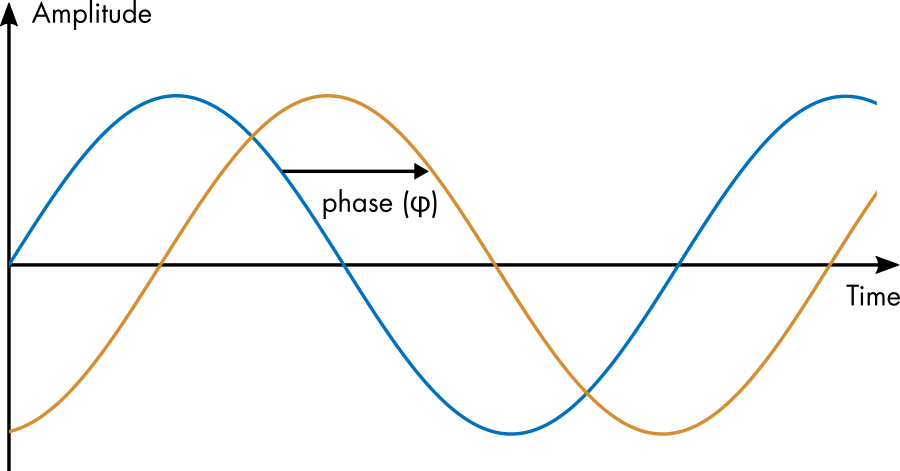

*The phase or phase shift of a signal is how far it has been shifted horizontally. *

Real signals do not typically have zero phase, and so the Fourer sine series is insufficient to represent them. However, adding a cosine series allows you to produce signals with any phase. 

### **Definition**

One common definition for the Fourier series is the combination of cosine and sine series:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


With this addition, there are now two sets of coefficients: the cosine series coefficients $a_n$ and the sine coefficients $b_n$. The sine terms have a phase of $0^\circ$ while the cosine signals have a phase of $90^\circ$ (assuming that zero phase corresponds to a sine signal). If you combine a cosine and sine signal with the same frequency, it produces a phase shifted signal:


$$a \cos (\omega t) + b \sin( \omega t) = c \sin( \omega t  -  \phi)$$


where the phase shift is determined by the ratio of the coefficients $a$ and $b$. 

    **Activity. **Create phase shifted signals using Fourier series by completing the tasks below.

**Task 1. **Open the Interactive Fourier Series app.

[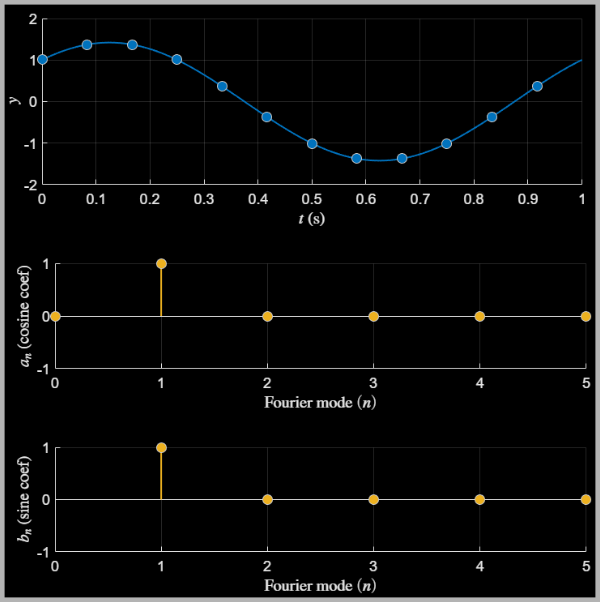](matlab: InteractiveFourierSeries)

[InteractiveFourierSeries.mlapp](matlab: InteractiveFourierSeries)

In the app, $L = 1/2$ by default, so the the period of the Fourier series is 1 s. This implies that the fundamental mode with index $n = 1$ has a frequency of 1 Hz. To adjust the mode coefficients, click and drag the yellow circles. For this exercise, do not drag the blue circles.

**Task 2. **Adjust the Fourier coefficients to create a 1 Hz signal with zero phase ($\phi = 0 ^\circ$) (relative to a sine function).

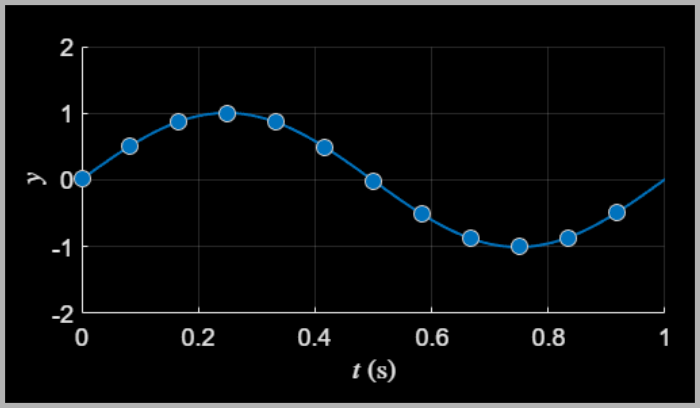

**Task 3.** Adjust the Fourier coefficients to create a 2 Hz signal with a phase shift of $\phi = 90 ^\circ$ (relative to a sine function).

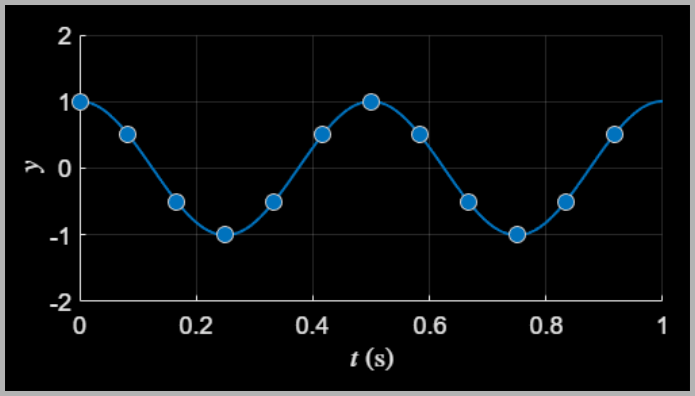

**Task 4.** A 1 Hz signal with a phase shift of $\phi = 45^\circ$ (relative to a sine function).

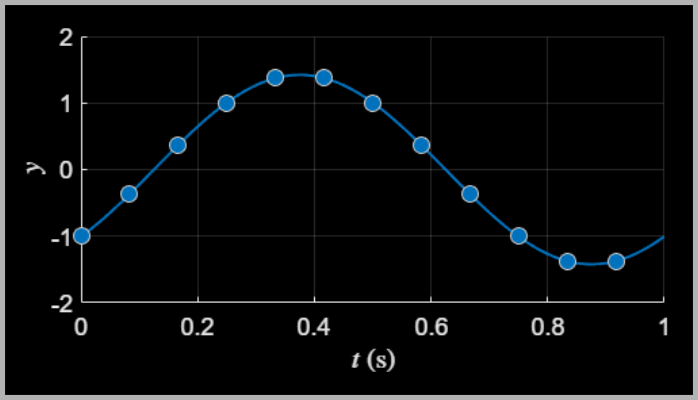

## Solving for Fourier Series Coefficients

The guitar A note audio signal clearly has at least 3 frequencies. 

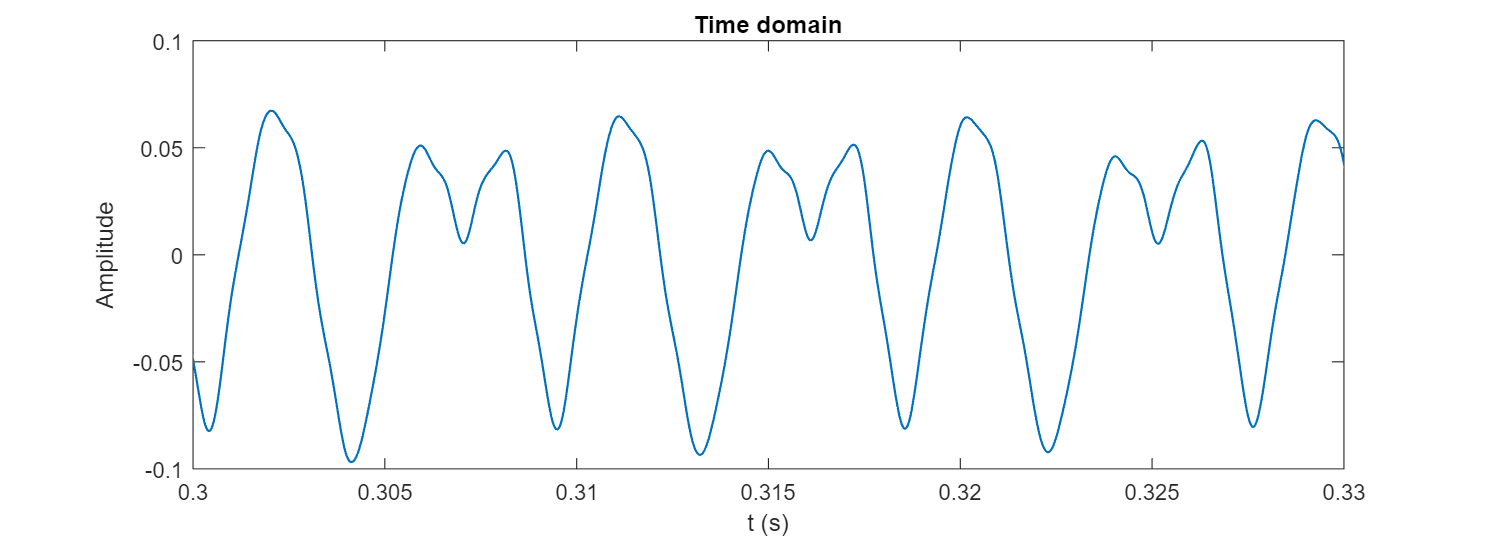

% This code plays the guitar sound and plots part of the signal
[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)
plotGuitarSignal(yGuitar,FsGuitar,[0.3,0.33])

But what are the frequencies and how strongly is each represented? In other words, what does the guitar audio signal look like in the frequency domain?

### Fourier Coefficient Formulas

In the previous activities, you adjusted the Fourier coefficients by hand. Fortunately, this isn't necessary to identify the Fourier series coefficients of a given signal. You can identify the coefficients of a $2L$ periodic function using two formulas:


$$a_n = \frac{1}{L} \int_{-L}^{L} y(t) \cos \left( \frac{ n \pi }{L} t \right) dt$$



$$b_n = \frac{1}{L} \int_{-L}^{L} y(t) \sin\left( \frac{ n \pi }{L} t \right) dt$$


These integrals calculate the weight of the $n^{th}$ mode required to match the given signal, $y(t)$. These expressions are independent because the basis functions (the sines and cosines) are orthogonal to each other.

    **Activity. **The Fourier modes of the guitar signal are estimated using the integral formulas and plotted below. Run the section to see the guitar A note in the frequency domain.

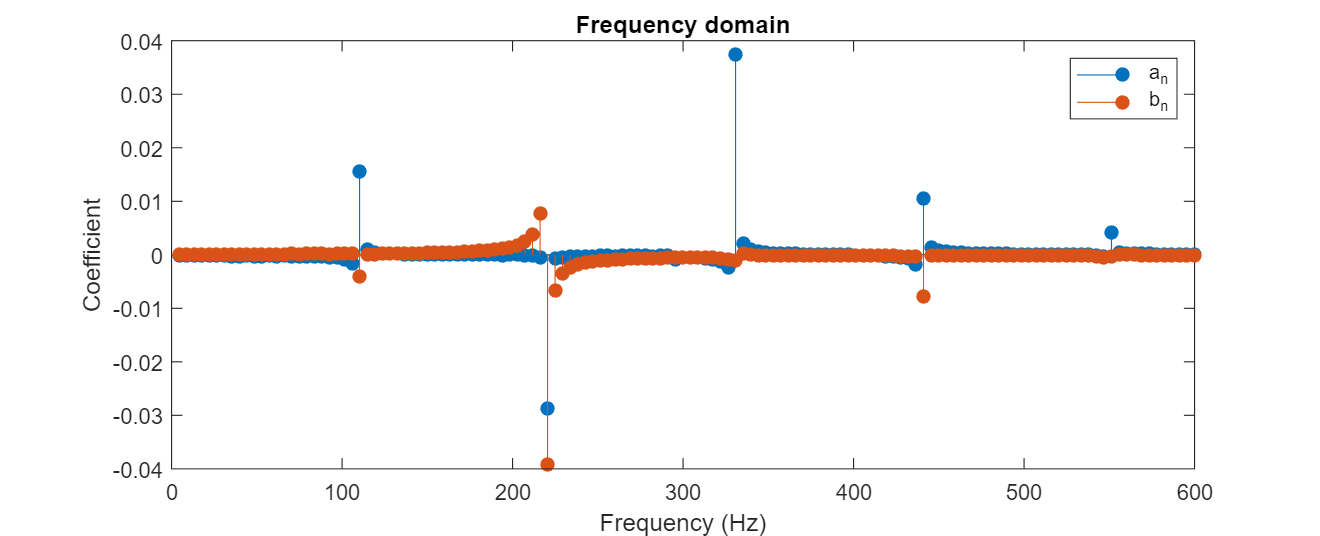

% Helper function that estimates and plots the Fouier coefficients
computeGuitarFourierCoef(yGuitar,FsGuitar) 

Try clicking on a peak to create a data tip. You can use this to identify the frequency of a mode.

**  Reflect.** 

- Which frequency is dominant?

- Are the dominant frequencies purely sine or cosine? 

- Based on the observed coefficients, can you make any general statements about the phase of each mode?

### Analytic Fourier Series Coefficients

Because the guitar signal is a sampled recording, the Fourier series coefficients must be estimated numerically. However, if you have an analytic function, you can compute the Fourier coefficients using standard integrals.

 **Example. **Compute the Fourier coefficients of 


$$y(t) = 3 \cos(24 \pi t ) - 6 \sin (10 \pi  t)$$


assuming that $L = 0.5$ s.

Because $L = 0.5$, the Fourier series will have the form


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( 2 n \pi  t \right) + b_n \sin \left( 2 n \pi  t \right)$$


Comparing $y(t)$ to the Fourier series, it is clear that $a_n = 0$ except for $n = 12$ and $b_n = 0$ except for $n = 5$. Applying the integral formula for $a_{12}$:


$$ \begin{array}{rl} a_{12} &= \frac{1}{L} \int_{-L}^{L} y(t) \cos \left( \frac{ n \pi }{L} t \right) dt
\\
&=  2 \int_{-0.5}^{0.5} 3 \cos (24 \pi t) \cos \left( 24 \pi t \right)  - 6 \sin \left( 10 \pi t \right) \cos \left( 24 \pi t \right)dt
\\
&=  6 \int_{-0.5}^{0.5} \cos^2(24 \pi t) dt - 12  \int_{-0.5}^{0.5} \sin \left( 10 \pi t \right) \cos \left( 24 \pi t \right)dt
\end{array}
$$


Notice that the second integrand is the product of an odd (sine) and even (cosine) function, so it is odd. This implies that on the domain [-0.5,0.5], the second integral is zero. You can use a trigonometric identity to evaluate the first integral, or refer to an integral table. The result is


$$a_{12} =  6 \int_{-0.5}^{0.5} \cos^2(24 \pi t) dt = 6 \cdot 0.5 = 3
$$


This should be what you would expect by examining the original function $y(t)$. Compute the integral for the second term to find that $b_5 = -6$.

Run this section to see the function in the time domain and the Fourier coefficients in the frequency domain plotted below.

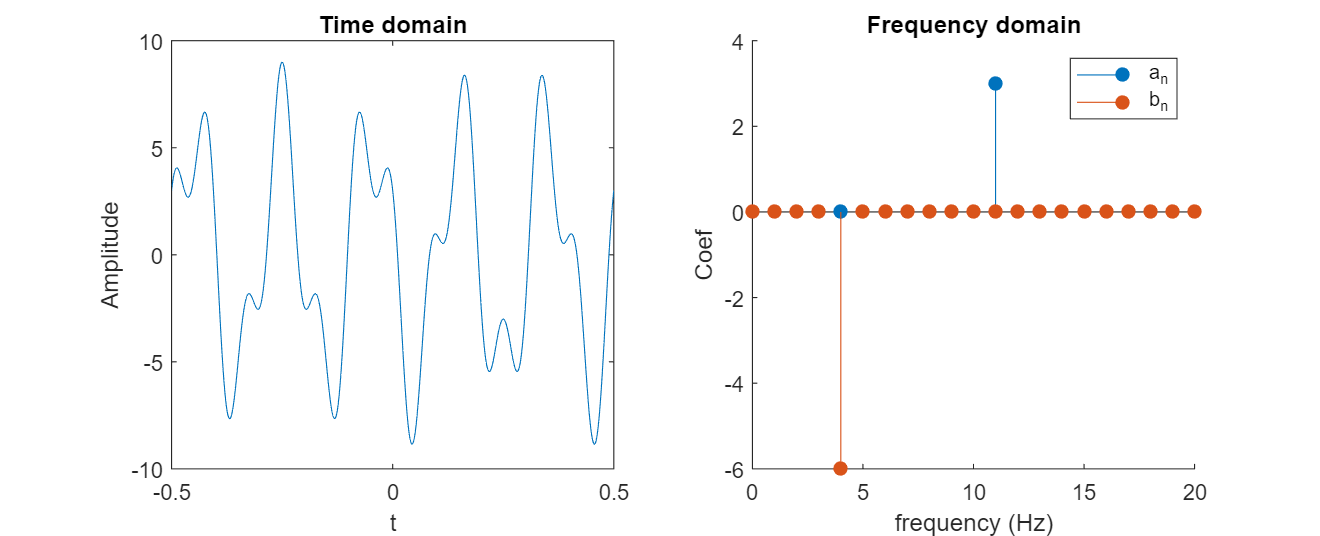

% The time domain signal
t = linspace(-0.5,0.5,500);
y = 3*cos(24*pi*t) - 6*sin(10*pi*t);

% Define the frequencies and the vectors for an and bn
freq = 0:20;
an = zeros(1,21);
bn = zeros(1,21);
an(12) = 3;
bn(5) = -6;

createFreqPlot(t, y, freq, an, bn); % Helper function that creates the plot

 **Exercise.** In this exercise, you will compute Fourier coefficients of a given function.

The 3 essential modes of the guitar A note audio recording can be represented by the function


$$y = 1.6 \sin( 2 \pi  \cdot110 t) + 4.8 \sin( 2 \pi \cdot 220 t) + 3.7 \sin( 2 \pi \cdot 330 t)$$


Note that the phase has been neglected and the function has been rescaled to make it easier to work with.

**Task 1.** By inspection, identify the Fourier series coefficients $a_n$ and $b_n$ in the definition


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


Assume that $L = 0.5$ s. 

**Task 2. **Use the integral formulas to analytically compute the first Fourier coefficient. Continue to assume that $L = 0.5$ s.  Does the results match what you calculated in **Task 1**?

**Task 3. **Complete the plot of the Fourier domain below by setting the values of `an` and `bn` to match your calculations in the previous tasks.

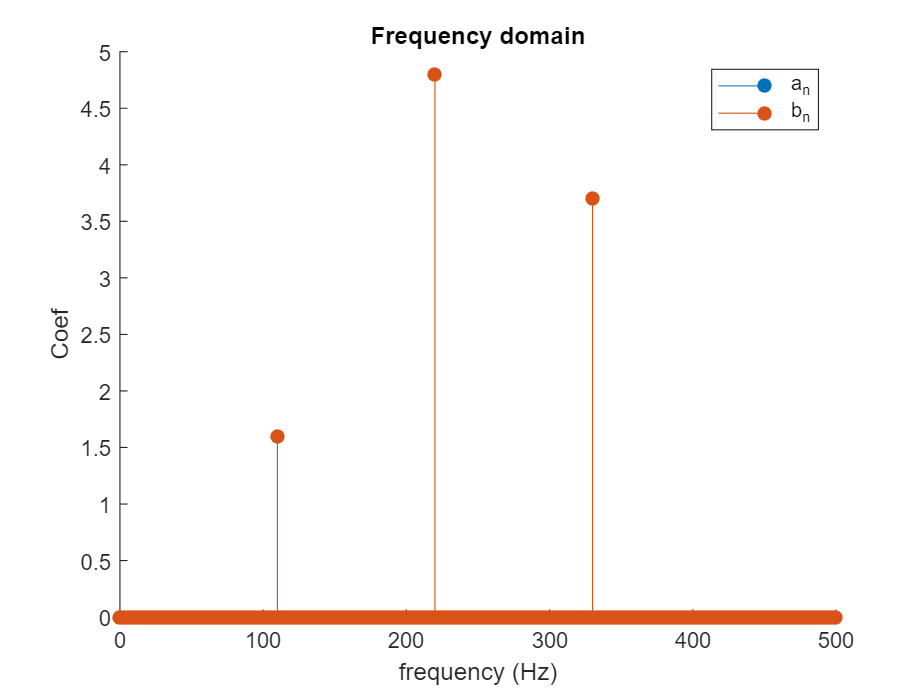

% Define the frequencies and the vectors for an and bn
freq = 0:500;
an = zeros(1,501);
bn = zeros(1,501);

% Adjust an and bn here to use the coefficients you calculated
% in Tasks 1 and 2.
bn(111) = 1.6;
bn(221) = 4.8;
bn(331) = 3.7;

% Create the plot
figure
hold on
stem(freq,an,"Filled")
stem(freq,bn,"Filled")
hold off
title("Frequency domain")
xlabel("frequency (Hz)")
ylabel("Coef")
legend("a_n","b_n")

You can also evaluate the Fourier series of other (periodic) functions. The process is the same: define the interval $L$ and then use the integral formulas to calculate the Fourier series coefficients.

 **Example. **Solve for the Fourier series of the odd square wave with period $2L$ and plot the result.

The odd square wave is pictured below. The coefficient integral is taken on the interval $[-L,L]$.

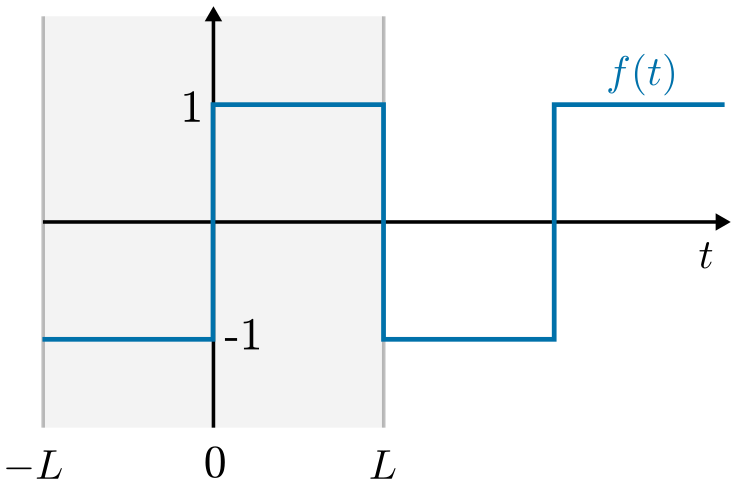

*Odd square wave*

The cosine coefficients $a_n$ are given by


$$a_n = \frac{1}{L} \int_{-L}^{L} f(t) \cos \left( \frac{ n \pi}{L} t \right) dt$$


Because $f(t)$ is odd and the cosine function is even, their product is odd. This implies that the integral is zero, so $a_n = 0$.

To solve for the sine coefficients $b_n$, split the integral on the intervals $[-L,0]$ and $[0,L]$.


$$\begin{array}{rl}
b_n &= \frac{1}{L} \int_{-L}^{L} f(t) \sin \left( \frac{n \pi }{L} t \right) dt 
\\
&=  \frac{1}{L} \left[ - \int_{-L}^{0}  \sin \left( \frac{n \pi}{L} t \right) dt + 
\int_{0}^{L} \sin \left( \frac{ n \pi}{L} t \right) dt  \right]
\end{array}$$


Evaluate the integral to find


$$\begin{array}{rl}
b_n &=  \frac{1}{n \pi} \left[ \left. \cos \left( \frac{n \pi}{L} t \right) \right|_{-L}^0 - 
\left. \cos \left( \frac{n \pi}{L} t \right) \right|_0^L  \right]
\\
&=  \frac{2}{n \pi} \left[ 1 - \cos(n \pi )]
\end{array}$$


Notice that for even $n$, $\cos( n \pi) = 1$, while if $n$ is odd $\cos(n \pi ) = -1$. This implies


$$b_n =
\left\{
\begin{array}{ll} 
0 & n \ \text{ even}
\\
\frac{4}{n \pi} & n \ \text{ odd}
\end{array}
\right.$$


Therefore, the Fourier series approximation of the square wave is


$$f_s(t) = \sum_{n=1,3,5,\ldots}^\infty \frac{4}{n \pi} \sin \left( \frac{ n \pi } {L}  t \right)$$


Use the slider below to view the partial series plotted alongside the original square wave function.

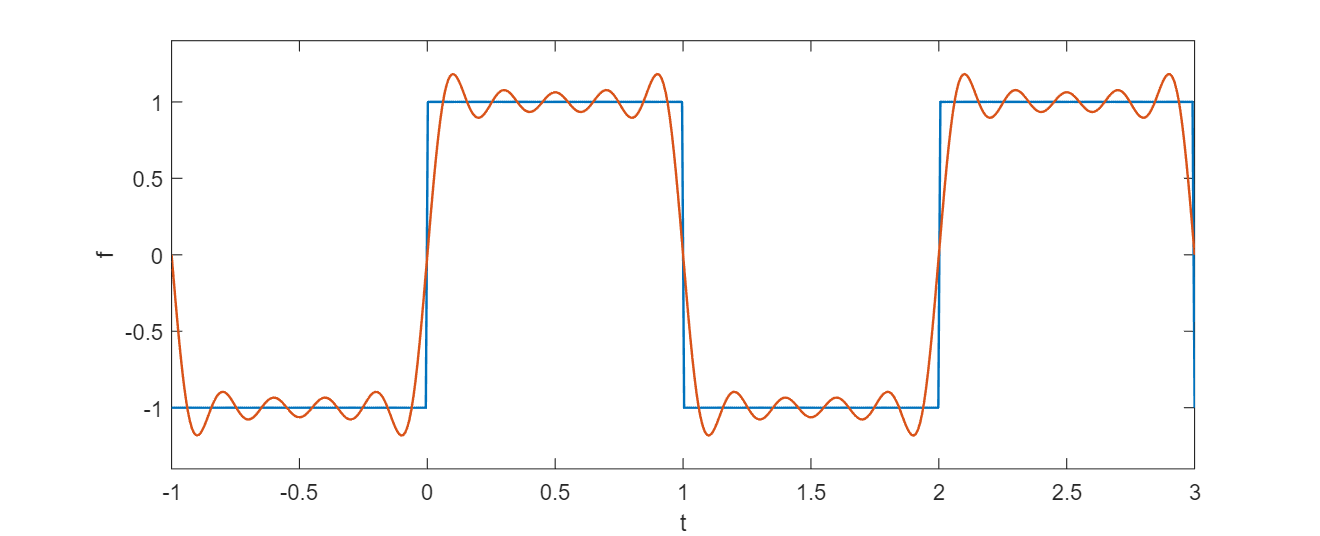

NModes = 5; % How many modes to use
plotSquareWaveSeries(NModes); % Helper function that generates the plot

**Helper Functions**

function plotSingleSine(A, f)
    % Time domain
    t = linspace(0,0.01,500);
    g = A*sin(2*pi*f*t);
    
    % Frequency domain
    freq = 0:500;
    ghat = zeros(1,501);
    ghat(f+1) = A;
    
    figure("position",[1,1,800,325])
    % Time domain plot
    subplot(1,2,1)
    plot(t,g,"linewidth",1)
    ylim([-3,3])
    title("Time domain")
    xlabel("time (s)")
    ylabel("$y$","Interpreter","latex")
    
    % Frequency domain plot
    subplot(1,2,2)
    stem(freq,ghat,"filled")
    ylim([0,3])
    title("Frequency domain")
    xlabel("frequency (Hz)")
    ylabel("$\hat{y}$","Interpreter","latex")
end

function plotGuitarSignal(yGuitar,FsGuitar,timeLimits)
    tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable    
    % Generate the plot
    figure("position",[1,1,900,325]) 
    plot(tGuitar,yGuitar(:,1),"Linewidth",1)
    xlim(timeLimits)
    xlabel("t (s)")
    ylabel("Amplitude")
    title("Time domain")
end

function computeGuitarFourierCoef(y,Fs)
    Nmodes = 1000;
    yc = y(1e4:2e4);
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % The domain is assumed to be 2L
    f = (1:Nmodes)/(2*L); % Frequencies

    % Estimate coefficients using trapezoid rule
    a = zeros(1,Nmodes);
    b = zeros(1,Nmodes);
    a0 = 1/L*trapz(tc,yc);
    for n = 1:Nmodes
        a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
        b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
    end

    % Plot the result
    figure("position",[1,1,900,325])
    stem(f,a,"Filled")
    hold on
    stem(f,b,"Filled")
    hold off
    xlabel("Frequency (Hz)")
    ylabel("Coefficient")
    legend("a_n","b_n")
    title("Frequency domain")
    xlim([0,600])
end

function createFreqPlot(t, y, freq, an, bn)
    % Create the plot
    figure("position",[1,1,900,325])
    subplot(1,2,1)
    plot(t,y)
    title("Time domain")
    xlabel("t")
    ylabel("Amplitude")
    
    subplot(1,2,2)
    hold on
    stem(freq,an,"Filled")
    stem(freq,bn,"Filled")
    hold off
    title("Frequency domain")
    xlabel("frequency (Hz)")
    ylabel("Coef")
    legend("a_n","b_n")
end

function plotSquareWaveSeries(NModes)
    % Compute the coefficients
    L = 1;
    n = 1:2:(NModes*2);
    b = 4./(pi*n);
    
    % Sum the Fourier modes
    t = linspace(-L,3*L,500);
    fs = zeros(size(t));
    for k = 1:numel(n)
        fs = fs + b(k)*sin((n(k)*pi/L).*t);
    end
    f = square(t*pi/L);
    
    % Plot the result
    figure("position",[1,1,800,325])
    plot(t,f,t,fs,"linewidth",1.1)
    axis([-L,3*L,-1.4,1.4])
    xlabel("t")
    ylabel("f")
end